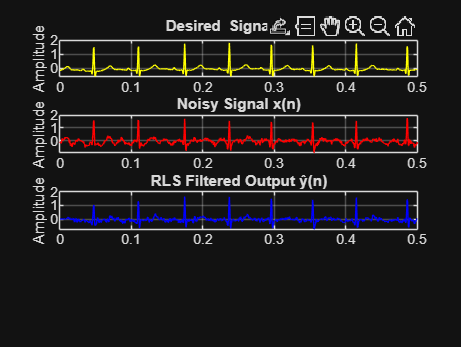

load('/MATLAB Drive/BSP_assignment2/Weiner filtering/idealECG.mat');  % should load yi (ideal ECG), optionally Fs
if ~exist('Fs','var') || isempty(Fs)
    Fs = 500; % Hz
end
yi = idealECG(:); 
N  = length(s);               % Number of samples
t = linspace(0,5,N)';    % Time vector  

% Desired signal (same as before)
%s = sawtooth(2*pi*2*t(1:N,1), 0.5);   

% Noise (non-stationary + WGN)
phi = pi/6;
n1 = 0.2*sin(2*pi*50*t(1:N/2,1) - phi);
n2 = 0.3*sin(2*pi*100*t(N/2+1:N,1) - phi);
nwg = awgn(yi, 10, 'measured') - yi;
eta = [n1;n2];
noise = eta + nwg;

x = yi + noise;
r_n = 0.3 * (nwg + sin(2*pi*50*t + pi/6) + sin(2*pi*100*t + pi/4));

%% RLS Adaptive Filter
M = 10;                  % Filter order
lambda = 0.99;           % Forgetting factor
delta = 0.01;            % Small constant
w = zeros(M,1);          % Initial weights
P = (1/delta)*eye(M);    % Initial inverse correlation matrix

y_hat_rls = zeros(N,1);  % Filter output
e_rls = zeros(N,1);      % Error

for n = M:N
    r = r_n(n:-1:n-M+1);   % Input vector
    k = (P*r) / (lambda + r'*P*r);   % Gain vector
    alpha = x(n) - w'*r;            % A priori error
    w = w + k*alpha;                 % Update weights
    P = (1/lambda)*(P - k*r'*P);     % Update P
    y_hat_rls(n) = w'*r;             % Output
    e_rls(n) = x(n) - y_hat_rls(n); % Error
end

%% Plots
figure;
subplot(4,1,1);
plot(t, yi, 'y','LineWidth',0.5); grid on;
title('Desired Signal y_i(n)'); ylabel('Amplitude');
xlim([0 0.5])

subplot(4,1,2);
plot(t, x, 'r'); grid on;
title('Noisy Signal x(n)'); ylabel('Amplitude');
xlim([0 0.5])

subplot(4,1,3);
plot(t, e_rls, 'b','LineWidth',0.2); grid on;
title('RLS Filtered Output ŷ(n)'); ylabel('Amplitude');
xlim([0 0.5])